x = load('1.txt')

x =      0     0     0     0     0   404
     1     0     0     0     0   392
     2     0     0     0     0   372
     3     0     0     0     0   353
     4     0     0     0     0   342
     5     0     0     0     0   348
     6     0     0     0     0   347
     7     0     0     0     0   339
     8     0     0     0     0   334
     9     0     0     0     0   333



S=x(:,6);

waveletFunction = 'db8';
[C,L] = wavedec(S,8,waveletFunction);

cD1 = detcoef(C,L,1); %NOISY
cD2 = detcoef(C,L,2); %NOISY
cD3 = detcoef(C,L,3); %NOISY
cD4 = detcoef(C,L,4); %NOISY
cD5 = detcoef(C,L,5); %GAMA
cD6 = detcoef(C,L,6); %BETA
cD7 = detcoef(C,L,7); %ALPHA
cD8 = detcoef(C,L,8); %THETA
cA8 = appcoef(C,L,waveletFunction,8); %DELTA


%%%% Calculation the Details Vectors
D1 = wrcoef('d',C,L,waveletFunction,1); %NOISY
D2 = wrcoef('d',C,L,waveletFunction,2); %NOISY
D3 = wrcoef('d',C,L,waveletFunction,3); %NOISY
D4 = wrcoef('d',C,L,waveletFunction,4); %NOISY
D5 = wrcoef('d',C,L,waveletFunction,5); %GAMMA
D6 = wrcoef('d',C,L,waveletFunction,6); %BETA
D7 = wrcoef('d',C,L,waveletFunction,7); %ALPHA
D8 = wrcoef('d',C,L,waveletFunction,8); %THETA
A8 = wrcoef('a',C,L,waveletFunction,8); %DELTA


sp=10101

sp = 10101

ep=12100

ep = 12100


s=S(sp:ep) %RAW

s =         1018
        1018
        1018
        1018
         929
         939
         994
        1018
        1018
        1018


d5=D5(sp:ep) %GAMMA

d5 =   -32.2721
  -33.1374
  -34.0888
  -35.2036
  -36.5099
  -37.7982
  -38.9176
  -40.3753
  -42.4949
  -45.3404


d6=D6(sp:ep) %BETA

d6 =    88.5954
   89.1840
   89.1943
   88.6423
   87.5448
   85.9175
   83.7942
   81.2162
   78.2397
   74.9469


d7=D7(sp:ep) %ALPHA

d7 =    46.6384
   45.9259
   45.1872
   44.4226
   43.6324
   42.8179
   41.9791
   41.1154
   40.2257
   39.3075


d8=D8(sp:ep) %THETA

d8 =    59.0578
   59.8335
   60.5938
   61.3385
   62.0672
   62.7797
   63.4758
   64.1552
   64.8177
   65.4640


a8=A8(sp:ep) %DELTA

a8 =   829.4028
  830.0074
  830.6040
  831.1925
  831.7730
  832.3454
  832.9098
  833.4664
  834.0154
  834.5571



%{
%%%plotting the alph, beta, gamma, theta etc
plot(s), title("Raw")   %%raw
plot(d5), title("gamma")  %%beta
plot(d6), title("beta")   %%beta
plot(d7), title("alpha")   %%alpha
plot(d8), title("theta")   %%theta
plot(a8), title("delta")   %%theta

%}
sT = transpose(s)

sT =         1018        1018        1018        1018         929         939         994        1018        1018        1018        1018        1018         967         969         979         969         921         856         799         753         719         703         696         691         710         743         775         808         842         878         927         996        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018        1018         927         900


d5T = transpose(d5)

d5T =   -32.2721  -33.1374  -34.0888  -35.2036  -36.5099  -37.7982  -38.9176  -40.3753  -42.4949  -45.3404  -49.1210  -53.7974  -59.3924  -66.2598  -74.4264  -83.4819  -92.9049 -101.8342 -109.5345 -115.9009 -120.8176 -124.2500 -126.2036 -126.1889 -123.8870 -119.2964 -112.2743 -102.7888  -90.7962  -75.9957  -58.3670  -38.3469  -16.4690    6.4707   29.7151   52.9848   75.9442   98.2370  119.5118  139.0049  156.0286  170.1035  180.7052  187.5300  190.3552  188.9055  183.1758  173.4565  160.2721  144.5298


d6T = transpose(d6)

d6T =    88.5954   89.1840   89.1943   88.6423   87.5448   85.9175   83.7942   81.2162   78.2397   74.9469   71.4047   67.6452   63.6911   59.5407   55.1887   50.6602   45.9559   41.0468   35.9276   30.6134   25.1387   19.5862   14.0220    8.4537    2.9073   -2.5834   -7.9967  -13.2847  -18.4176  -23.4078  -28.2447  -32.8905  -37.3110  -41.4544  -45.2820  -48.8040  -52.0304  -54.9735  -57.6630  -60.1193  -62.3814  -64.5219  -66.5898  -68.5969  -70.5401  -72.3773  -74.0664  -75.6073  -76.9703  -78.0964


d7T = transpose(d7)

d7T =    46.6384   45.9259   45.1872   44.4226   43.6324   42.8179   41.9791   41.1154   40.2257   39.3075   38.3595   37.3826   36.3787   35.3507   34.3025   33.2362   32.1559   31.0676   29.9761   28.8852   27.7978   26.7144   25.6365   24.5696   23.5181   22.4864   21.4791   20.4980   19.5455   18.6254   17.7397   16.8892   16.0733   15.2895   14.5359   13.8141   13.1255   12.4727   11.8580   11.2806   10.7404   10.2391    9.7767    9.3535    8.9685    8.6185    8.3011    8.0160    7.7627    7.5407


d8T = transpose(d8)

d8T =    59.0578   59.8335   60.5938   61.3385   62.0672   62.7797   63.4758   64.1552   64.8177   65.4640   66.0941   66.7076   67.3036   67.8803   68.4363   68.9706   69.4823   69.9695   70.4309   70.8649   71.2701   71.6461   71.9917   72.3050   72.5842   72.8272   73.0320   73.1977   73.3232   73.4076   73.4502   73.4504   73.4081   73.3240   73.1984   73.0309   72.8209   72.5674   72.2695   71.9277   71.5420   71.1122   70.6386   70.1210   69.5594   68.9546   68.3072   67.6168   66.8835   66.1066


a8T = transpose(a8)

a8T =   829.4028  830.0074  830.6040  831.1925  831.7730  832.3454  832.9098  833.4664  834.0154  834.5571  835.0919  835.6198  836.1407  836.6548  837.1618  837.6619  838.1548  838.6401  839.1177  839.5874  840.0493  840.5038  840.9508  841.3904  841.8225  842.2470  842.6641  843.0737  843.4759  843.8705  844.2573  844.6364  845.0080  845.3722  845.7293  846.0790  846.4213  846.7560  847.0830  847.4021  847.7131  848.0158  848.3097  848.5950  848.8714  849.1393  849.3986  849.6494  849.8918  850.1257



%signals = [sT, d5T, d6T, d7T, d8T, a8T];
signals = [s, d5, d6, d7, d8, a8];

num = []


num =

     []



temp = []


temp =

     []



for i=1:6
    for j=1:2000
        num = [num, i];
    end
    num = transpose(num)
    temp = [temp, num]
    num = []
end

num =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


temp =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



num =

     []



num =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


temp =      1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2



num =

     []



num =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


temp =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3



num =

     []



num =      4
     4
     4
     4
     4
     4
     4
     4
     4
     4


temp =      1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4



num =

     []



num =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


temp =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5



num =

     []



num =      6
     6
     6
     6
     6
     6
     6
     6
     6
     6


temp =      1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6



num =

     []





seq = 1:1:2000;
seq=transpose(seq);
seq6 = [seq, seq, seq, seq, seq, seq];



plot3(temp,seq6, signals)




%Lomb-Scargle Power Spectrum Estimation 
plomb_s = plomb(s, [], "power", "Pd", []), title("Raw")

plomb_s = 	1.0e+04 *

    0.1751
    0.2781
    0.5909
    0.5115
    0.2591
    0.1202
    0.3821
    0.8883
    1.0926
    0.8966


plomb_d5 =plomb(d5, [], "power", "Pd", []), title("gamma") 

plomb_d5 =     2.3995
    1.7265
    0.6919
    0.0025
    1.0457
    1.7315
    0.7373
    0.0049
    1.0299
    1.7429


plomb_d6 =plomb(d6, [], "power", "Pd", []), title("beta")

plomb_d6 = 	1.0e+03 *

    0.0000
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0001
    0.0001
    0.0000
    0.0000


plomb_d7 =plomb(d7, [], "power", "Pd", []), title("alpha")

plomb_d7 = 	1.0e+03 *

    0.0000
    0.0001
    0.0002
    0.0002
    0.0001
    0.0001
    0.0004
    0.0005
    0.0002
    0.0002


plomb_d8 =plomb(d8, [], "power", "Pd", []), title("theta") 

plomb_d8 = 	1.0e+03 *

    0.0020
    0.0026
    0.0036
    0.0015
    0.0011
    0.0039
    0.0047
    0.0007
    0.0045
    0.0285


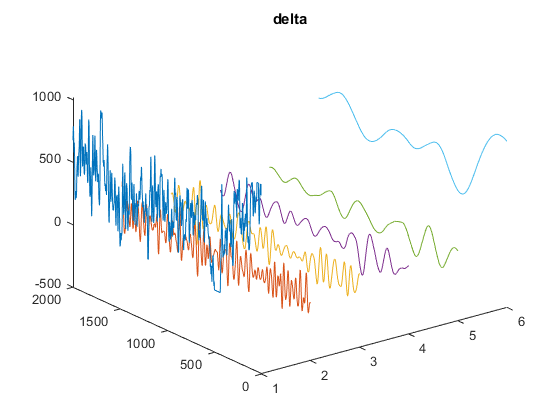

plomb_a8 = 	1.0e+04 *

    0.2003
    0.2901
    0.5751
    0.4930
    0.2650
    0.1453
    0.3859
    0.8834
    1.1374
    1.0189


plomb_a8 =plomb(a8, [], "power", "Pd", []), title("delta") 

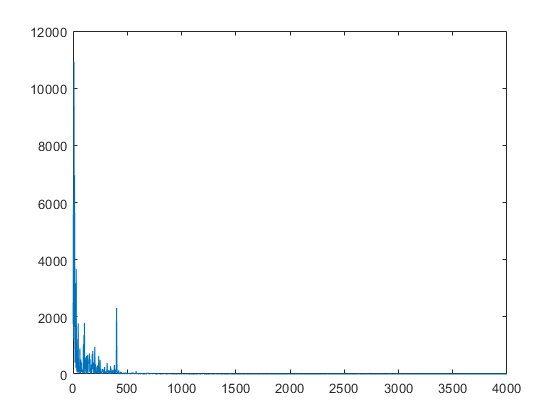


plot(plomb_s)

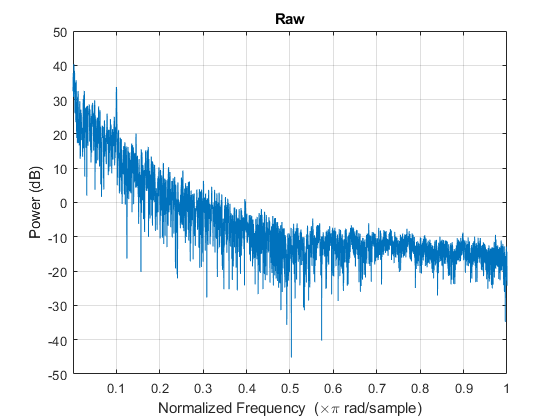

plomb(s, [], "power", "Pd", []), title("Raw")

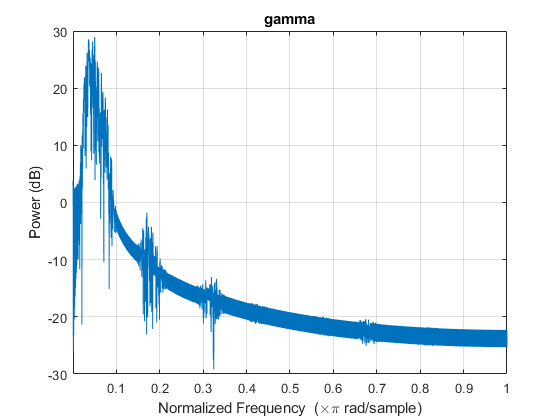

plomb(d5, [], "power", "Pd", []), title("gamma") 

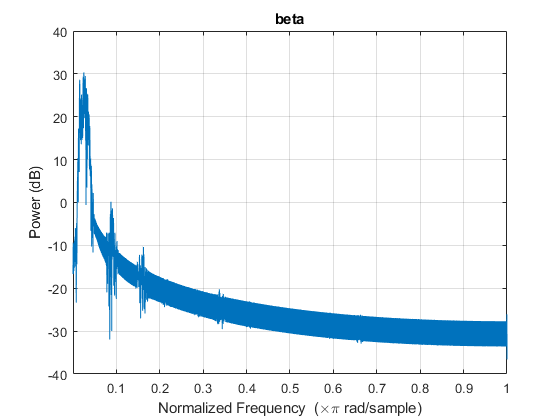

plomb(d6, [], "power", "Pd", []), title("beta")

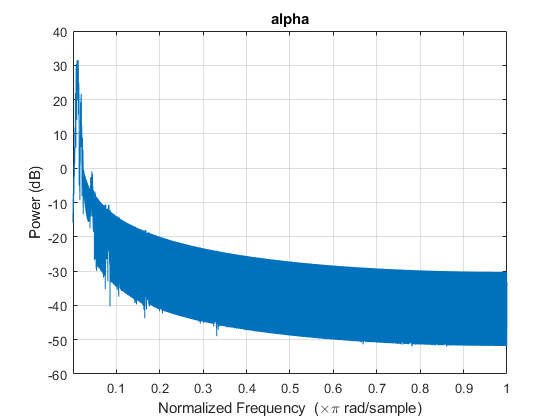

plomb(d7, [], "power", "Pd", []), title("alpha")

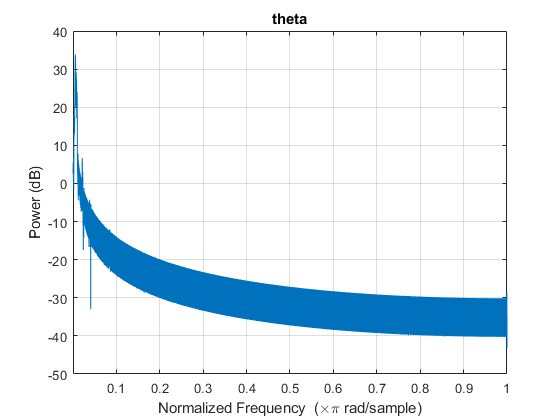

plomb(d8, [], "power", "Pd", []), title("theta") 

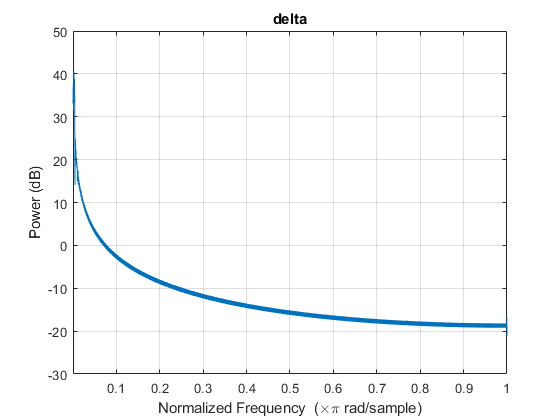

plomb(a8, [], "power", "Pd", []), title("delta") 

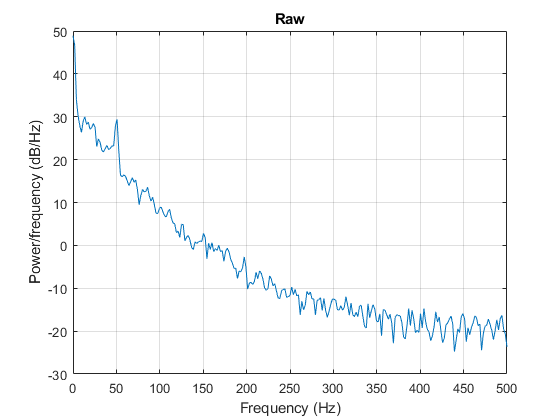




%Welch Power Spectral Density Estimation
figure; pwelch(s, [], [], [], 1000), title("Raw")

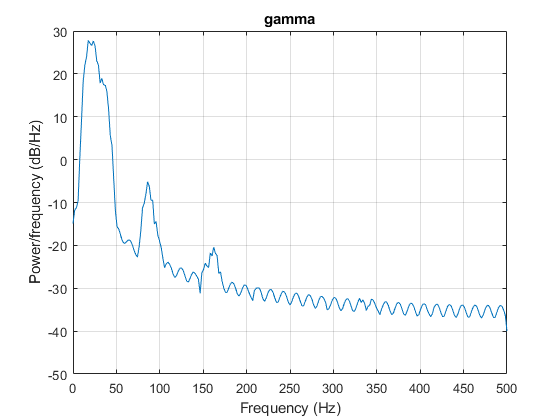

figure; pwelch(d5, [], [], [], 1000), title("gamma") 

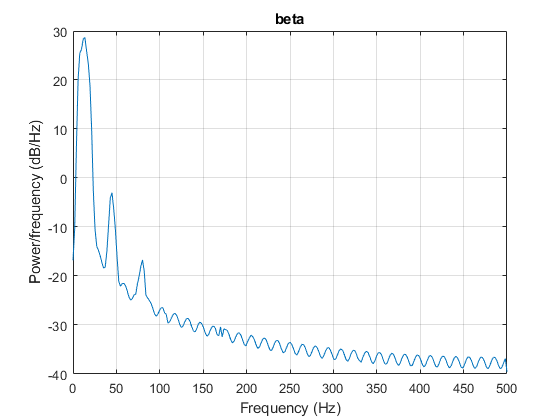

figure; pwelch(d6, [], [], [], 1000), title("beta")

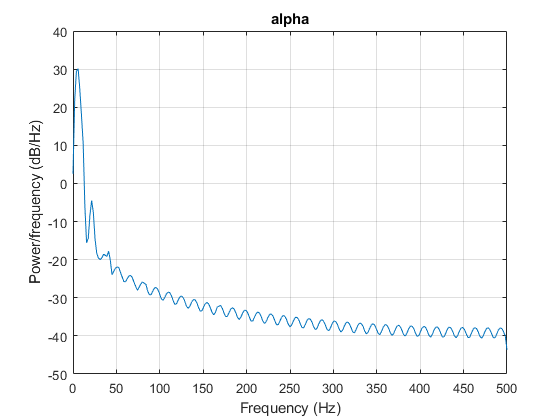

figure; pwelch(d7, [], [], [], 1000), title("alpha")

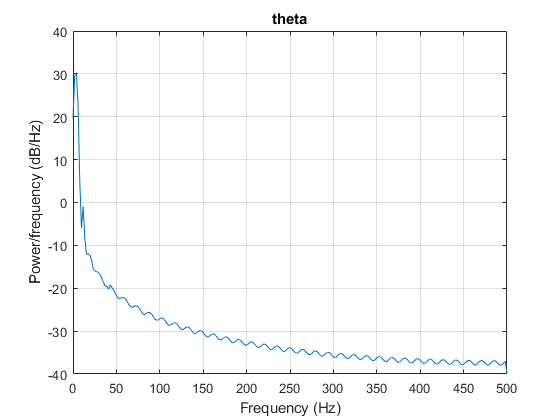

figure; pwelch(d8, [], [], [], 1000), title("theta") 

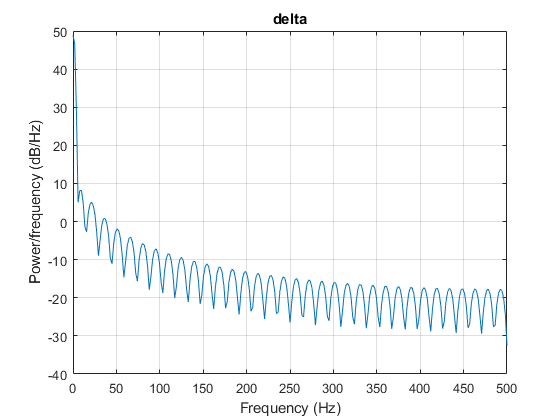

figure; pwelch(a8, [], [], [], 1000), title("delta") 

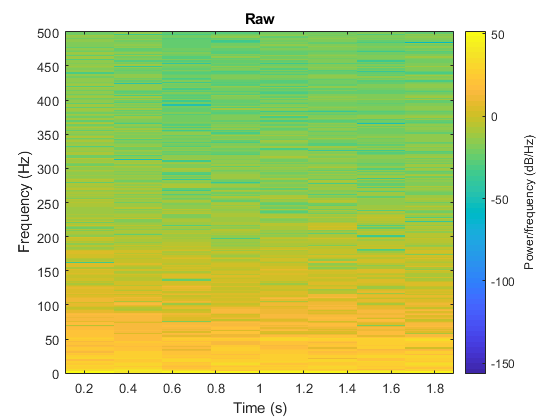


%spectrograms
figure; spectrogram(s, [],[], [], 1000, 'yaxis'), title("Raw")

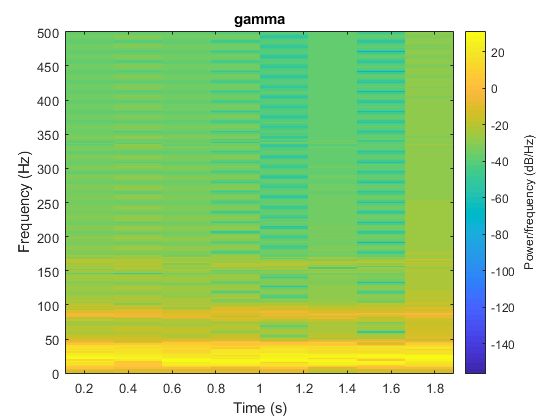

figure; spectrogram(d5, [],[], [], 1000, 'yaxis'), title("gamma") 

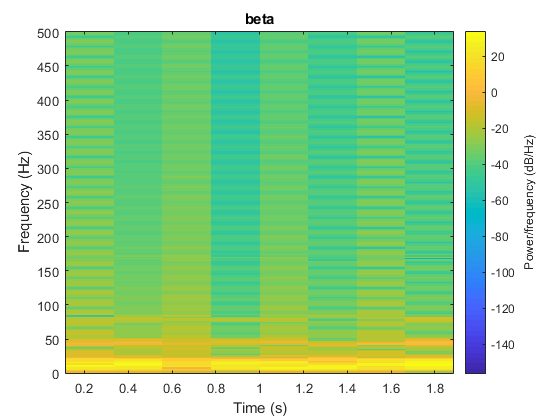

figure; spectrogram(d6, [],[], [], 1000, 'yaxis'), title("beta")

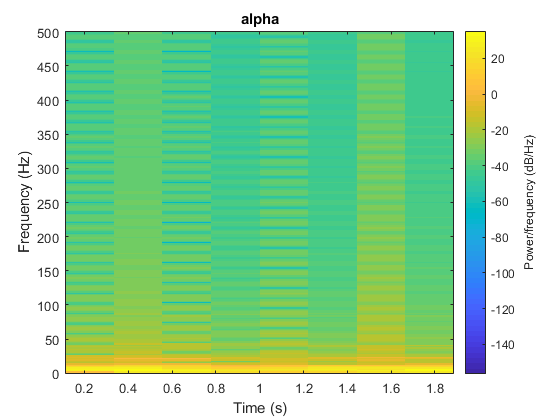

figure; spectrogram(d7, [],[], [], 1000, 'yaxis'), title("alpha")

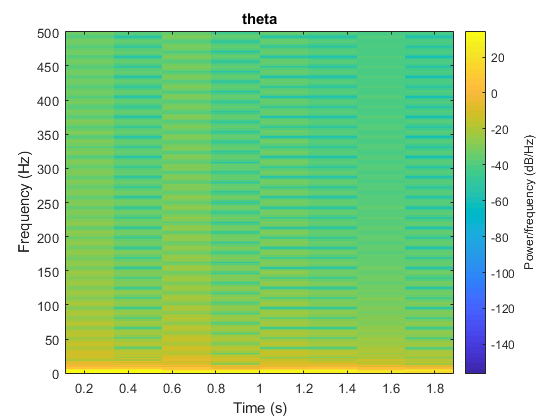

figure; spectrogram(d8, [],[], [], 1000, 'yaxis'), title("theta") 

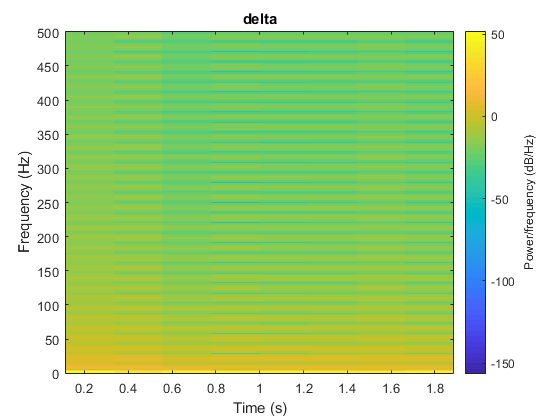

figure; spectrogram(a8, [],[], [], 1000, 'yaxis'), title("delta") 